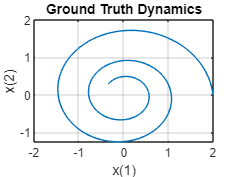

%Neural ODE - Example

%%Generating Ground Truth Data.
addpath('C:\Users\LEGION\Documents\GitHub\guilda');
x0 = [2; 0]; %Initial point
A = [-0.1 -1; 1 -0.1]; %Real Dynamics
trueModel = @(t,y) A*y; %True Model

numTimeSteps = 2000; %Time steps
T = 15; % Final Time
odeOptions = odeset(RelTol=1.e-7); %Tolerance of the ODE
t = linspace(0, T, numTimeSteps); %Time interval
[~, xTrain] = ode45(trueModel, t, x0, odeOptions);
%[t,y] = ode45()
xTrain = xTrain';
figure
plot(xTrain(1,:),xTrain(2,:))
title("Ground Truth Dynamics") 
xlabel("x(1)") 
ylabel("x(2)")
grid on

%%Model Parameters
neuralOdeTimesteps = 40; %compared to the 2000
dt = t(2); %the delta of time
timesteps = (0:neuralOdeTimesteps)*dt; %make 40 time steps separated by dt.

neuralOdeParameters= struct;
stateSize = size(xTrain,1); %The size of the first dimension (rows)
hiddenSize = 20; %The hidden layers.

%Parameter 1
neuralOdeParameters.fc1 = struct; %Learnable parameter.
sz = [hiddenSize stateSize];
neuralOdeParameters.fc1.Weights = initializeGlorot(sz, hiddenSize, stateSize);

'initializeGlorot' is used in the following examples:
  Define Text Decoder Model Function
  Define Text Encoder Model Function
  Generate Text Using Autoencoders
  Language Translation Using Deep Learning
  Multil

%Glorot = Xavier (uniform distribution with bounds)
neuralOdeParameters.fc1.Bias = initializeZeros([hiddenSize 1]); %20 rows 1 column zeros

%Parameter 2 
neuralOdeParameters.fc2 = struct;
sz = [stateSize hiddenSize];
neuralOdeParameters.fc2.Weights = initializeGlorot(sz, stateSize, hiddenSize)
neuralOdeParameters.fc2.Bias = initializeZeros([stateSize 1]);

%Display the learnable parameters of the model
neuralOdeParameters.fc1
neuralOdeParameters.fc2